seconds = 10;
dt = .05;
timesteps = seconds/dt;
m = 1;
g = 9.81;

A = [1, 0, 0, dt, 0, 0; 
      0, 1, 0, 0, dt, 0;
      0, 0, 1, 0, 0, dt;
      0, 0, 0, 1, 0, 0;
      0, 0, 0, 0, 1, 0;
      0, 0, 0, 0, 0, 1];

B = [0, 0, 0, 0;
     0, 0, 0, 0;
     0, 0, 0, 0;
    dt/m, 0, 0, 0;
    0, dt/m, 0, 0;
    0, 0, dt/m, 0];

X = zeros([timesteps, size(A, 2)]);
X(1, 1) = 5;
X(1, 2) = 1;
X(1, 3) = 10;

c = [0, 0, 0, 0, 0, -g*dt];


U = zeros([timesteps-1, size(B, 2)]);

Q = eye(size(A, 2)) * 10;
R = eye(size(B, 2));

q = zeros(1, size(A, 2));
r = zeros(1, size(B, 2));

xCon = 10000;
uMax = 15;
uMin = 4;

tol = 1e-3;
penalty = .1;

tiny = TinyMPC(X, U, A, B, c, Q, R, q, r, xCon, uMax, tol, timesteps, 15, penalty);

tiny = tiny.run();
disp(tiny.K)

    2.8586         0         0    3.7989         0         0
         0    2.8586         0         0    3.7989         0
         0         0    2.8586         0         0    3.7989
         0         0         0         0         0         0



tiny.U

ans =    -1.4958   -0.2992    0.9466    0.9397
   -1.4711   -0.2942    0.9421    0.9351
   -1.4492   -0.2898    0.9425    0.9354
   -1.4304   -0.2861    0.9482    0.9410
   -1.4149   -0.2830    0.9594    0.9523
   -1.4029   -0.2806    0.9768    0.9698
   -1.3948   -0.2790    1.0010    0.9942
   -1.3909   -0.2782    1.0329    1.0264
   -1.3917   -0.2783    1.0737    1.0676
   -1.3980   -0.2796    1.1250    1.1193


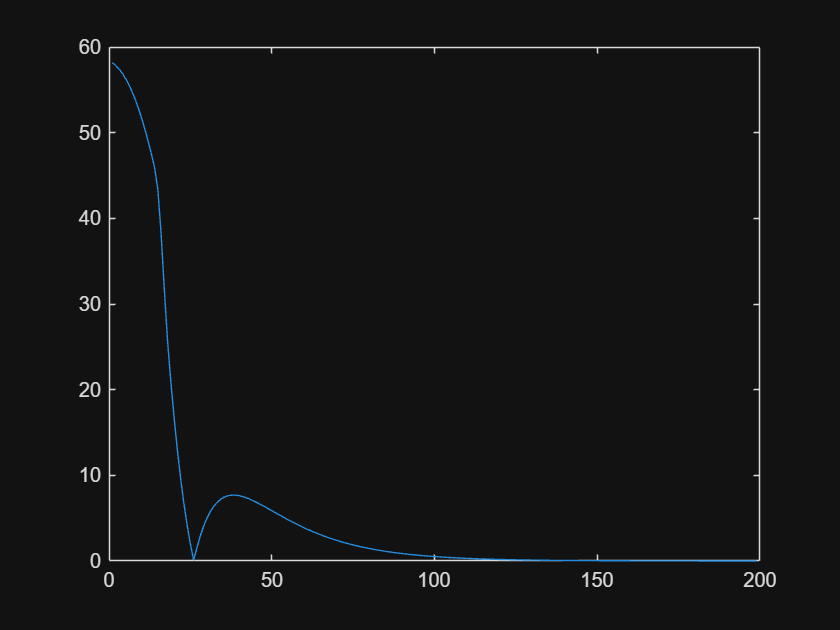

plot(rad2deg(acos(tiny.U(:, 3) ./ vecnorm(squeeze(tiny.U(:, 1:3)), 2, 2))))

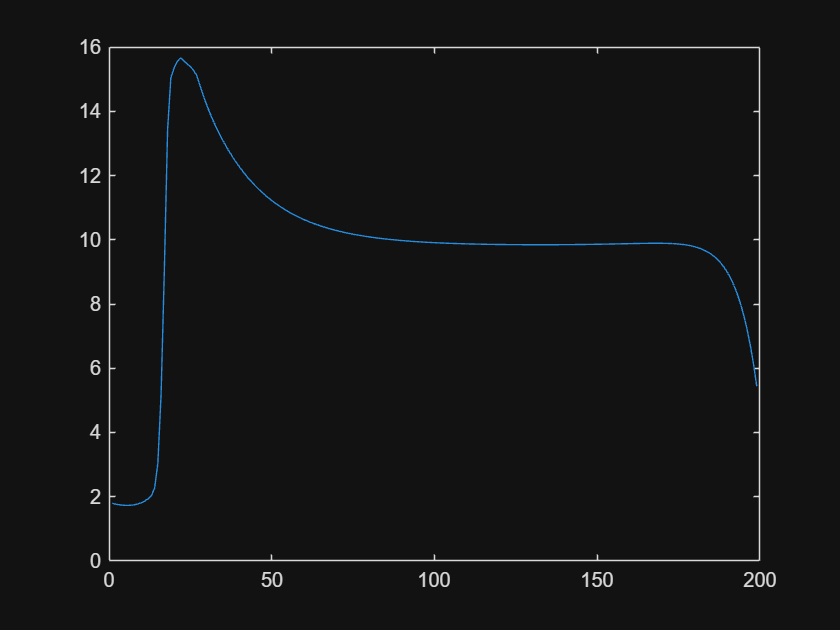

plot(vecnorm(squeeze(tiny.U(:, 1:3)), 2, 2))

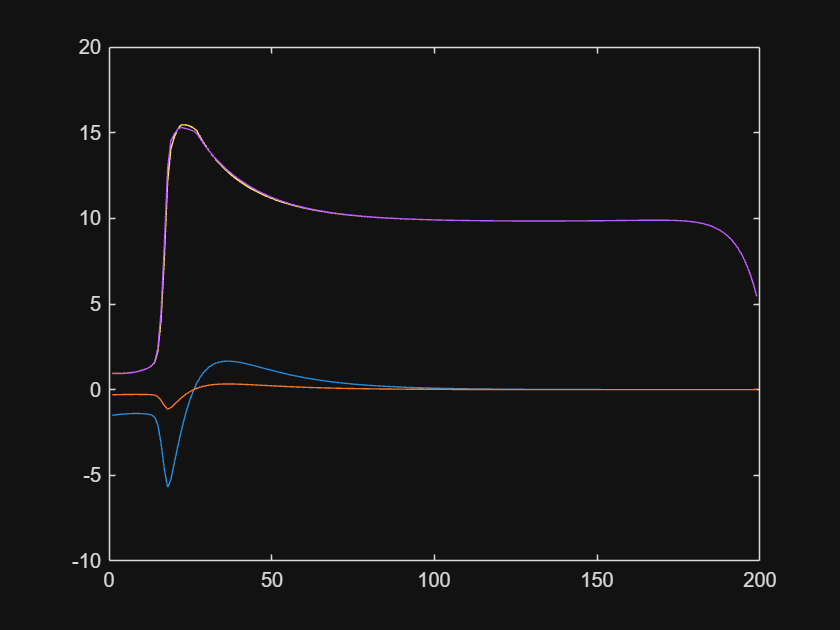

plot(tiny.U)

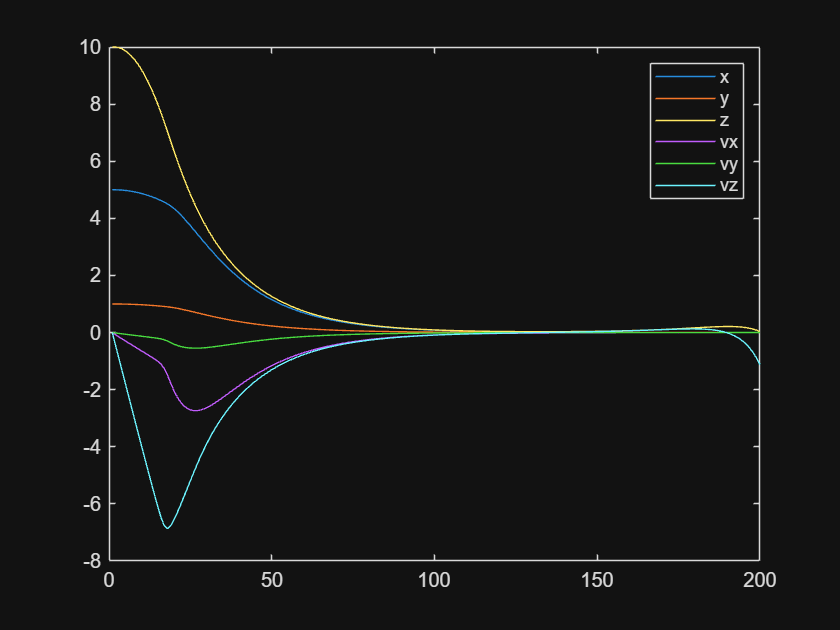

plot(tiny.X)
legend("x", "y", "z", "vx", "vy", "vz")